**读取数据**

clear 

sigds = signalDatastore("F:\科研 sxh\MIE数据\深度学习\数据增强" , ...
    "IncludeSubfolders",true, ...
    "SignalVariableNames",["CH1", "BF","BMI"], ...
     "ReadOutputOrientation","row");

% 获取文件数目
numFiles = numel(sigds.Files);
% 初始化一个 cell 数组储存来文件长度
filelength = cell(numFiles, 1);

**提取特征**

ALLfeatures=[];%所有人的肌电特征
j=1;
while hasdata(sigds)
    features=[];%每个人的肌电特征        
    EMG = cell2mat(read(sigds)); %循环所有文件 
    num_samples = length(EMG);
    filelength{j} = EMG(1,2:end); %网络输出
    window_size= 50; % 窗口大小
    step_size = round(window_size * 0.5);% 重叠率0.5
    num_windows = floor((num_samples - window_size) / step_size) + 1;% 循环终点次数
    % 提取的特征feature_funcs = {@sd, @var, @max,@fzc, @emav, @tm,@iemg, @rms, @zc,@ssc}; 
    
    for i = 1:num_windows
        start_idx = (i - 1) * step_size + 1;
        end_idx = start_idx + window_size - 1;
        window_data = EMG(start_idx:end_idx,1);
        sd= jfemg('sd', window_data);
        var= jfemg('var', window_data);
       
        fzc= jfemg('fzc', window_data);
        emav= jfemg('emav', window_data);
        tm= jfemg('tm', window_data);
        iemg= jfemg('iemg', window_data);
        rms= jfemg('rms', window_data);
        zc= jfemg('zc', window_data);
        ssc= jfemg('ssc', window_data);
        % 在这里添加你对窗口数据的特征提取操作
        % 对特征函数应用 transform 函数
       
        feature = [sd,var,fzc, emav, tm,iemg, rms, zc,ssc];
        features=[features;feature];
    end


主成分分析

    % 特征归一化（标准化）
    normalized_features = zscore(features);
    % r=corrcoef(normalized_features); 获取相关系数矩阵
    coeff = pca(normalized_features);
    disp('主成分分析的主成分系数：');
    disp(coeff);
    
    % 将数据投影到前两个主成分上
    num_components = 3;
    PCAfeature = normalized_features * coeff(:, 1:num_components);

%     PCAfeatures=[PCAfeature';EMG(1:length(normalized_features),2)';EMG(1:length(normalized_features),3)',;EMG(1:length(normalized_features),5)'];
%     features=mat2cell(PCAfeatures,1);
    ALLfeatures{j}=PCAfeature';
    j=j+1
end

主成分分析的主成分系数：


    0.4150    0.0262    0.0261   -0.0237   -0.2398   -0.0400   -0.5002   -0.2855   -0.6596
    0.3780    0.2761   -0.1666    0.0238    0.2424    0.7821    0.2002   -0.2011    0.0410
   -0.0614    0.5197    0.7579   -0.3851    0.0589   -0.0010    0.0063   -0.0016    0.0005
    0.4028   -0.1032    0.0799   -0.0857   -0.3431   -0.3092    0.6499   -0.4129    0.0849
    0.3211    0.3497   -0.2461    0.0380    0.6564   -0.5306   -0.0043    0.0144   -0.0047
    0.4165    0.0283    0.0108   -0.0390   -0.2067    0.0300    0.2027    0.8410   -0.1793
    0.4151    0.0285    0.0245   -0.0230   -0.2385   -0.0404   -0.4933    0.0081    0.7238
   -0.1665    0.6250   -0.0835    0.6485   -0.3814   -0.0761    0.0535   -0.0111    0.0009
   -0.2058    0.3575   -0.5680   -0.6475   -0.2944   -0.0361   -0.0055   -0.0026   -0.0001



j = 2

主成分分析的主成分系数：


    0.4087    0.0870    0.0485    0.0001   -0.1590    0.0555    0.5535    0.5564    0.4228
    0.3985    0.1487    0.0773    0.0608   -0.0882    0.7725   -0.4201    0.0976   -0.1377
   -0.0878    0.7724   -0.4985   -0.3817    0.0289   -0.0235   -0.0039    0.0047   -0.0039
    0.4015   -0.0224    0.0227   -0.1384   -0.2363   -0.5559   -0.4013    0.3836   -0.3815
    0.2950    0.2888    0.1598    0.3797    0.7876   -0.1905   -0.0536    0.0073    0.0187
    0.4084    0.0333    0.0317   -0.0815   -0.2085   -0.2027   -0.2625   -0.5484    0.6085
    0.4091    0.0895    0.0493    0.0056   -0.1443    0.0044    0.5313   -0.4825   -0.5350
   -0.2401    0.4549    0.2113    0.6714   -0.4742   -0.1153   -0.0421    0.0045    0.0001
   -0.1627    0.2716    0.8179   -0.4794    0.0273   -0.0006    0.0152   -0.0023    0.0012



j = 3

主成分分析的主成分系数：


    0.4120    0.0748    0.0270   -0.0508   -0.1757   -0.0765   -0.5363    0.5849    0.3936
    0.3943    0.1880    0.0868    0.0928   -0.0511    0.8448    0.2221    0.0933   -0.1370
   -0.0897    0.7245   -0.4517   -0.4893    0.1529   -0.0123    0.0071    0.0013   -0.0022
    0.4053   -0.0298    0.0038   -0.1660   -0.2096   -0.4250    0.5510    0.3542   -0.3920
    0.2846    0.2947    0.2307    0.4104    0.7454   -0.2309    0.0375    0.0073    0.0113
    0.4124    0.0394    0.0222   -0.0927   -0.1859   -0.1215    0.2972   -0.5298    0.6331
    0.4123    0.0754    0.0279   -0.0455   -0.1666   -0.1115   -0.5164   -0.4928   -0.5212
   -0.2221    0.5397    0.0961    0.5902   -0.5289   -0.1387    0.0523    0.0086   -0.0052
   -0.1791    0.2189    0.8508   -0.4409   -0.0391   -0.0033   -0.0112   -0.0020    0.0001



j = 4

主成分分析的主成分系数：


    0.4132    0.0741    0.0514   -0.0136   -0.1503   -0.0429    0.5583    0.5907    0.3687
    0.4013    0.1302    0.0935    0.0611   -0.0935    0.8312   -0.2903    0.0899   -0.1326
   -0.0780    0.8245   -0.2471   -0.4858    0.1289   -0.0166   -0.0077    0.0015   -0.0018
    0.4063   -0.0189    0.0086   -0.1340   -0.2235   -0.4852   -0.4970    0.3454   -0.4060
    0.2860    0.1986    0.2695    0.3723    0.7973   -0.1618   -0.0733    0.0117    0.0142
    0.4128    0.0309    0.0315   -0.0755   -0.1942   -0.1630   -0.2795   -0.5023    0.6537
    0.4137    0.0757    0.0555   -0.0070   -0.1334   -0.0745    0.5208   -0.5208   -0.5041
   -0.2233    0.5012    0.2605    0.6372   -0.4580   -0.1151   -0.0455    0.0048   -0.0021
   -0.1541   -0.0015    0.8848   -0.4379   -0.0359    0.0084    0.0140   -0.0012    0.0007



j = 5

主成分分析的主成分系数：


    0.4097    0.0832    0.0415    0.0660   -0.1737   -0.0051    0.5427   -0.5462    0.4428
    0.3979    0.1757    0.0921   -0.1075    0.0037    0.8225   -0.2958   -0.0928   -0.1347
   -0.0737    0.7180   -0.5623    0.3732    0.1529   -0.0109   -0.0107   -0.0031   -0.0004
    0.4013   -0.0274    0.0132    0.2129   -0.2255   -0.4469   -0.5089   -0.3952   -0.3564
    0.2867    0.2952    0.2197   -0.4708    0.6854   -0.2993   -0.0300   -0.0083    0.0208
    0.4099    0.0330    0.0281    0.1298   -0.1865   -0.1321   -0.2856    0.5811    0.5847
    0.4103    0.0839    0.0402    0.0624   -0.1611   -0.0658    0.5227    0.4463   -0.5625
   -0.2275    0.5218    0.1937   -0.5173   -0.5968   -0.1085   -0.0546   -0.0041   -0.0020
   -0.1926    0.2800    0.7650    0.5382    0.0948    0.0226    0.0125    0.0039    0.0006



j = 6

主成分分析的主成分系数：


    0.4310    0.0131    0.0799    0.1104    0.1506   -0.4268   -0.3132   -0.4500   -0.5386
    0.3796    0.3825   -0.1139   -0.1667   -0.0641   -0.2016    0.7413   -0.2222    0.1584
   -0.0758    0.3476    0.8660    0.1223   -0.3288    0.0174   -0.0056   -0.0046    0.0027
    0.4083   -0.1846    0.1090    0.2445    0.1330    0.6661   -0.0386   -0.4311    0.2806
    0.2325    0.5824   -0.2725   -0.3797   -0.2738    0.3292   -0.4346    0.0958   -0.0828
    0.4269   -0.0733    0.0940    0.1784    0.1336    0.2404    0.2443    0.6564   -0.4533
    0.4317    0.0180    0.0770    0.1047    0.1460   -0.3965   -0.3195    0.3495    0.6275
   -0.2354    0.4600    0.1177   -0.0376    0.8418    0.0949   -0.0100   -0.0034    0.0015
   -0.1399    0.3768   -0.3405    0.8348   -0.1570   -0.0291   -0.0087    0.0014    0.0008



j = 7

主成分分析的主成分系数：


    0.4129    0.0888    0.0138    0.0113   -0.1571    0.1332    0.5375   -0.5466    0.4372
    0.4076    0.1369    0.0174    0.0714   -0.0285    0.7122   -0.5118   -0.1181   -0.1609
   -0.0803    0.6497   -0.5874   -0.4709    0.0666   -0.0147    0.0017   -0.0031   -0.0030
    0.4059   -0.0088    0.0344   -0.1372   -0.2513   -0.6025   -0.3138   -0.3832   -0.3791
    0.2999    0.2608    0.0513    0.3659    0.8078   -0.2288   -0.0094   -0.0004    0.0238
    0.4124    0.0394    0.0249   -0.0788   -0.2108   -0.2069   -0.2633    0.5498    0.6022
    0.4134    0.0894    0.0140    0.0143   -0.1451    0.0804    0.5282    0.4879   -0.5254
   -0.2125    0.5297    0.0161    0.6885   -0.4337   -0.0996   -0.0441   -0.0040   -0.0014
   -0.1265    0.4394    0.8060   -0.3740    0.0289    0.0189    0.0169    0.0007   -0.0009



j = 8

主成分分析的主成分系数：


    0.4106    0.0864    0.0546    0.0181   -0.1505    0.0686    0.5569    0.5831    0.3783
    0.4023    0.1294    0.0592    0.0908   -0.0996    0.7546   -0.4433    0.0989   -0.1554
   -0.0811    0.8328   -0.2527   -0.4787    0.0804   -0.0167   -0.0066    0.0040   -0.0041
    0.4036   -0.0145    0.0672   -0.1338   -0.2184   -0.5795   -0.3709    0.3500   -0.4133
    0.2939    0.2133    0.0625    0.4299    0.8043   -0.1715   -0.0523    0.0076    0.0193
    0.4100    0.0368    0.0622   -0.0705   -0.1993   -0.2068   -0.2688   -0.4913    0.6524
    0.4112    0.0878    0.0553    0.0230   -0.1345    0.0212    0.5282   -0.5350   -0.4857
   -0.2377    0.4570    0.1073    0.7081   -0.4512   -0.1288   -0.0393    0.0047   -0.0015
   -0.1421    0.1364    0.9501   -0.2295    0.0706    0.0237    0.0148   -0.0011    0.0006



j = 9

主成分分析的主成分系数：


    0.4087    0.0879    0.0280    0.0288   -0.1639    0.0579    0.5570   -0.4876   -0.4954
    0.4023    0.1290    0.0249    0.0934   -0.0576    0.7703   -0.4167   -0.1447    0.1445
   -0.0789    0.7630   -0.4707   -0.4343    0.0304   -0.0208   -0.0056   -0.0037    0.0032
    0.4031    0.0148    0.0561   -0.0872   -0.2507   -0.5746   -0.3931   -0.4199    0.3205
    0.3127    0.1953    0.0382    0.3137    0.8541   -0.1832   -0.0283   -0.0018   -0.0211
    0.4088    0.0555    0.0426   -0.0350   -0.2094   -0.1711   -0.2825    0.6232   -0.5343
    0.4094    0.0874    0.0298    0.0300   -0.1470    0.0107    0.5288    0.4202    0.5875
   -0.2274    0.4490    0.0195    0.7907   -0.3325   -0.0966   -0.0342   -0.0011    0.0005
   -0.1350    0.3779    0.8771   -0.2616    0.0246    0.0199    0.0139    0.0001   -0.0002



j = 10

主成分分析的主成分系数：


    0.4082    0.1070    0.0186    0.0121   -0.1509    0.0457    0.5606   -0.5278    0.4514
    0.4005    0.1356    0.0070    0.0585   -0.1215    0.7722   -0.4152   -0.1206   -0.1404
   -0.1076    0.6460   -0.6541   -0.3721    0.0686   -0.0119    0.0034   -0.0031   -0.0028
    0.4034    0.0355    0.0210   -0.1100   -0.2116   -0.5779   -0.3866   -0.3987   -0.3693
    0.2956    0.2275    0.0324    0.4074    0.8218   -0.1236   -0.0555   -0.0074    0.0139
    0.4082    0.0714    0.0145   -0.0602   -0.1921   -0.2062   -0.2815    0.5682    0.5856
    0.4088    0.1077    0.0184    0.0162   -0.1355    0.0060    0.5294    0.4744   -0.5450
   -0.2458    0.4747    0.0552    0.7234   -0.4209   -0.0974   -0.0362   -0.0025   -0.0009
   -0.1311    0.5078    0.7528   -0.3909    0.0729    0.0138    0.0014    0.0005   -0.0005



j = 11

主成分分析的主成分系数：


    0.4117    0.1038    0.0188    0.0016   -0.1515    0.0455    0.5423   -0.4887   -0.5113
    0.4049    0.1431    0.0095    0.0577   -0.0261    0.7805   -0.4065   -0.1384    0.1339
   -0.0981    0.5938   -0.6843   -0.4059    0.0667   -0.0151    0.0067   -0.0030    0.0039
    0.4048    0.0215    0.0268   -0.1325   -0.2494   -0.5564   -0.4131   -0.4180    0.3167
    0.3040    0.1956   -0.0207    0.3892    0.8187   -0.2125   -0.0403   -0.0003   -0.0190
    0.4117    0.0648    0.0174   -0.0751   -0.2001   -0.1654   -0.2708    0.6447   -0.5138
    0.4122    0.1029    0.0190    0.0076   -0.1375    0.0103    0.5408    0.3893    0.5967
   -0.2150    0.5372    0.0431    0.7010   -0.4038   -0.0797   -0.0504   -0.0024    0.0010
   -0.1226    0.5235    0.7264   -0.4072    0.1320   -0.0027    0.0070    0.0015   -0.0004



j = 12

主成分分析的主成分系数：


    0.4081    0.0596    0.0251   -0.0427   -0.2023   -0.1280   -0.5327   -0.4940   -0.4923
    0.3891    0.1915    0.1212    0.1183   -0.0016    0.8598    0.1217   -0.1267    0.1143
   -0.0825    0.7510   -0.4416   -0.4765    0.0840   -0.0031    0.0071   -0.0008    0.0007
    0.4015   -0.0378   -0.0030   -0.1583   -0.2504   -0.3406    0.5915   -0.4255    0.3202
    0.2948    0.3260    0.2509    0.3605    0.7226   -0.2966    0.0593   -0.0036   -0.0151
    0.4086    0.0297    0.0271   -0.0828   -0.2090   -0.0659    0.3159    0.6340   -0.5242
    0.4085    0.0623    0.0274   -0.0378   -0.1917   -0.1500   -0.4940    0.3959    0.6059
   -0.2375    0.4943    0.1130    0.6239   -0.5291   -0.1157    0.0621   -0.0082    0.0031
   -0.1920    0.1974    0.8441   -0.4524   -0.0817   -0.0118   -0.0159   -0.0001    0.0010



j = 13

主成分分析的主成分系数：


    0.4082    0.0833    0.0450    0.0134   -0.1606    0.1806   -0.5427   -0.6339    0.2636
    0.4028    0.1148    0.0531    0.0644   -0.1310    0.6657    0.5664   -0.0580   -0.1818
   -0.1057    0.8607   -0.1334   -0.4733    0.0769   -0.0152    0.0019   -0.0008   -0.0024
    0.4033   -0.0055    0.0440   -0.1218   -0.2084   -0.6389    0.2437   -0.2786   -0.4816
    0.2895    0.2458    0.1321    0.4748    0.7686   -0.1445    0.0284   -0.0161    0.0143
    0.4083    0.0341    0.0473   -0.0691   -0.1964   -0.2686    0.2469    0.3367    0.7349
    0.4089    0.0852    0.0483    0.0219   -0.1458    0.0983   -0.5128    0.6352   -0.3540
   -0.2531    0.4118    0.1098    0.6958   -0.5071   -0.1119    0.0205   -0.0073   -0.0001
   -0.1248    0.0224    0.9702   -0.2048    0.0042    0.0226   -0.0094    0.0001   -0.0009



j = 14

主成分分析的主成分系数：


    0.4108    0.0707    0.0304   -0.0058   -0.1784   -0.1161   -0.5426    0.6213    0.3156
    0.3940    0.1694    0.0105    0.1225   -0.0760    0.8579    0.1719    0.0855   -0.1494
   -0.0951    0.7660   -0.2814   -0.5668    0.0581   -0.0191    0.0029    0.0008   -0.0019
    0.4045   -0.0162    0.0603   -0.1247   -0.2290   -0.4049    0.5683    0.3038   -0.4304
    0.3022    0.2783    0.0352    0.3963    0.7950   -0.1920    0.0622    0.0115    0.0114
    0.4111    0.0418    0.0445   -0.0529   -0.1987   -0.1029    0.3036   -0.4441    0.6964
    0.4112    0.0726    0.0313   -0.0003   -0.1627   -0.1403   -0.5037   -0.5630   -0.4557
   -0.2344    0.4792   -0.0915    0.6906   -0.4563   -0.1370    0.0551    0.0046   -0.0035
   -0.1378    0.2552    0.9506   -0.1067   -0.0204    0.0177   -0.0144   -0.0005   -0.0001



j = 15

主成分分析的主成分系数：


    0.4052    0.0748    0.0454   -0.0214   -0.1836   -0.1289   -0.5318    0.5725    0.4085
    0.3896    0.1637    0.1039    0.0851   -0.0891    0.8608    0.1570    0.1062   -0.1365
   -0.0990    0.7658   -0.3298   -0.5383    0.0721   -0.0008    0.0027    0.0009    0.0008
    0.4012   -0.0043    0.0173   -0.1174   -0.2268   -0.4044    0.5919    0.3565   -0.3641
    0.3026    0.2461    0.2621    0.2457    0.8308   -0.1616    0.0476    0.0082    0.0112
    0.4058    0.0505    0.0420   -0.0536   -0.1987   -0.0989    0.2876   -0.5596    0.6189
    0.4055    0.0769    0.0483   -0.0212   -0.1689   -0.1560   -0.5046   -0.4697   -0.5466
   -0.2199    0.5487    0.1255    0.6968   -0.3577   -0.1366    0.0513    0.0054   -0.0044
   -0.2102    0.1047    0.8885   -0.3736   -0.1250   -0.0064   -0.0092    0.0005    0.0002



j = 16

主成分分析的主成分系数：


    0.4058    0.0526    0.0260   -0.0239   -0.1874   -0.1526   -0.5444   -0.4057   -0.5584
    0.3832    0.1735    0.1720    0.0393   -0.1391    0.8489    0.1505   -0.1517    0.0794
   -0.0946    0.7806   -0.4015   -0.4686    0.0282   -0.0097    0.0025   -0.0013   -0.0021
    0.4015   -0.0270   -0.0481   -0.0856   -0.2117   -0.4050    0.6090   -0.4532    0.2079
    0.2817    0.2521    0.4684    0.0123    0.7829   -0.1519    0.0388    0.0002   -0.0095
    0.4061    0.0362    0.0127   -0.0413   -0.2036   -0.1042    0.2744    0.7355   -0.4042
    0.4061    0.0555    0.0272   -0.0266   -0.1791   -0.1616   -0.4809    0.2568    0.6893
   -0.2197    0.5370    0.3335    0.6366   -0.3391   -0.1728    0.0444   -0.0083    0.0030
   -0.2467   -0.0265    0.6890   -0.6026   -0.3139   -0.0449   -0.0069    0.0010   -0.0003



j = 17

主成分分析的主成分系数：


     1     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0
     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     1



j = 18

主成分分析的主成分系数：


     1     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0
     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     1



j = 19

主成分分析的主成分系数：


    0.4152    0.0791   -0.0044   -0.0742    0.1536   -0.0984   -0.5462   -0.5447    0.4330
    0.3981    0.1719    0.0148    0.0816    0.1153    0.8493    0.2069   -0.1102   -0.1245
   -0.1056    0.5229    0.7404   -0.3859   -0.1338   -0.0177    0.0093   -0.0056   -0.0046
    0.4094   -0.0008   -0.0413   -0.1966    0.1361   -0.4290    0.5469   -0.3895   -0.3723
    0.2747    0.3189    0.0311    0.6391   -0.6153   -0.1809    0.0439   -0.0053    0.0141
    0.4157    0.0500   -0.0152   -0.1279    0.1465   -0.1279    0.3122    0.5655    0.5942
    0.4158    0.0802   -0.0025   -0.0660    0.1412   -0.1205   -0.5071    0.4687   -0.5523
   -0.2358    0.5204   -0.0516    0.4461    0.6703   -0.1412    0.0512   -0.0039   -0.0031
   -0.1164    0.5562   -0.6678   -0.4149   -0.2395    0.0323   -0.0224    0.0045    0.0018



j = 20

主成分分析的主成分系数：


    0.4197    0.0618   -0.0038   -0.1025    0.1615   -0.0678   -0.5322   -0.4481   -0.5429
    0.3995    0.1868    0.0405    0.1795    0.0115    0.8391    0.2116   -0.1221    0.0879
   -0.0943    0.4905    0.7333   -0.4260   -0.1764   -0.0097    0.0096   -0.0060    0.0025
    0.4105   -0.0319   -0.0459   -0.2421    0.1568   -0.3748    0.5749   -0.4526    0.2633
    0.2791    0.3105    0.0818    0.6583   -0.5156   -0.3446    0.0283    0.0045   -0.0155
    0.4197    0.0298   -0.0159   -0.1520    0.1498   -0.0989    0.2852    0.6996   -0.4434
    0.4200    0.0637   -0.0036   -0.0996    0.1548   -0.0924   -0.5058    0.2998    0.6568
   -0.2242    0.5502   -0.0291    0.3399    0.7175   -0.1123    0.0563   -0.0064    0.0028
   -0.0779    0.5618   -0.6713   -0.3677   -0.3019    0.0318   -0.0161    0.0022   -0.0018



j = 21

主成分分析的主成分系数：


    0.4363    0.0109   -0.1655    0.0011    0.1024   -0.2620   -0.4554   -0.5435    0.4475
    0.3869    0.3226    0.2840   -0.0574   -0.0098   -0.4933    0.5742   -0.1984   -0.2232
   -0.0894    0.4223   -0.4897   -0.6347   -0.4134    0.0098    0.0019   -0.0014   -0.0020
    0.4171   -0.1341   -0.2832    0.0433    0.0611    0.6424    0.2283   -0.3629   -0.3546
    0.2276    0.4878    0.6149   -0.0779   -0.1511    0.4529   -0.2809    0.0844    0.1100
    0.4334   -0.0430   -0.2067    0.0173    0.0801    0.1125    0.3462    0.5505    0.5703
    0.4368    0.0137   -0.1602    0.0009    0.1015   -0.2262   -0.4602    0.4726   -0.5355
   -0.2094    0.5147   -0.1815   -0.0125    0.8073    0.0771    0.0180   -0.0046   -0.0024
   -0.0600    0.4411   -0.3042    0.7652   -0.3514   -0.0197   -0.0033    0.0007   -0.0002



j = 22

主成分分析的主成分系数：


    0.4224    0.0408    0.0015   -0.0691   -0.1891   -0.0099   -0.5271   -0.2972   -0.6427
    0.4039    0.1110    0.0871    0.2173    0.1408    0.8056    0.2615   -0.1702    0.0597
   -0.0733    0.4685    0.7585   -0.4374    0.0914   -0.0111    0.0063   -0.0059    0.0012
    0.4096   -0.0297   -0.0499   -0.2171   -0.2627   -0.3853    0.5646   -0.4777    0.1317
    0.3206    0.1648    0.1329    0.4981    0.6417   -0.4382   -0.0095    0.0106   -0.0113
    0.4227    0.0179   -0.0045   -0.1042   -0.1837   -0.0529    0.2673    0.8014   -0.2448
    0.4225    0.0418    0.0020   -0.0678   -0.1873   -0.0304   -0.5109    0.1102    0.7113
   -0.1589    0.6181   -0.0221    0.5399   -0.5415   -0.0710    0.0487   -0.0052   -0.0003
    0.0076    0.5952   -0.6297   -0.3930    0.3051    0.0388   -0.0095    0.0035   -0.0006



j = 23

主成分分析的主成分系数：


    0.4202    0.0787    0.0012   -0.0401   -0.1286   -0.0192    0.5587   -0.3012   -0.6291
    0.4080    0.0948    0.0239    0.0826   -0.1126    0.8168   -0.3299   -0.1580    0.0598
   -0.0733    0.4484    0.8624   -0.2152    0.0507   -0.0211   -0.0173   -0.0103    0.0023
    0.4115    0.0217   -0.0433   -0.1927   -0.1625   -0.5111   -0.4785   -0.5010    0.1535
    0.3034    0.1122    0.0840    0.6441    0.6651   -0.1638   -0.0633    0.0064   -0.0145
    0.4193    0.0522   -0.0115   -0.1211   -0.1599   -0.1612   -0.2658    0.7794   -0.2774
    0.4206    0.0799    0.0023   -0.0335   -0.1198   -0.0420    0.5234    0.1601    0.7070
   -0.1885    0.5721   -0.1484    0.5456   -0.5511   -0.1127   -0.0329   -0.0024   -0.0013
   -0.0447    0.6590   -0.4739   -0.4239    0.3948    0.0596    0.0052    0.0020   -0.0003



j = 24

主成分分析的主成分系数：


    0.4418   -0.0046    0.1443    0.0551    0.0987   -0.4229   -0.3290    0.5652    0.4058
    0.3790    0.3089   -0.3238   -0.1785   -0.0556   -0.1682    0.6596    0.2779   -0.2839
   -0.0520    0.3470    0.6519   -0.5945   -0.3134    0.0139    0.0003    0.0035   -0.0043
    0.4067   -0.1806    0.2992    0.1691    0.0727    0.6915   -0.0424    0.3027   -0.3272
    0.2823    0.4078   -0.5148   -0.2697   -0.1430    0.3614   -0.4629   -0.1530    0.1661
    0.4371   -0.0629    0.1914    0.0899    0.0779    0.1291    0.3946   -0.5005    0.5756
    0.4425   -0.0023    0.1381    0.0527    0.0950   -0.4022   -0.2915   -0.4877   -0.5373
   -0.1576    0.5708    0.1451    0.0946    0.7838    0.0714    0.0022    0.0016   -0.0032
   -0.0400    0.5055    0.1345    0.7004   -0.4836   -0.0215   -0.0027   -0.0019    0.0020



j = 25

主成分分析的主成分系数：


    0.4178    0.0890   -0.0030   -0.0269   -0.1324   -0.0462    0.5585   -0.5094   -0.4751
    0.4071    0.1048    0.0156    0.0558   -0.1223    0.8266   -0.2952   -0.1359    0.1267
   -0.0757    0.4772    0.8223   -0.2902    0.0762   -0.0140   -0.0135   -0.0050    0.0037
    0.4113    0.0230   -0.0417   -0.1724   -0.1642   -0.5081   -0.4796   -0.4068    0.3437
    0.3049    0.1579    0.0516    0.5343    0.7583   -0.1182   -0.0693   -0.0017   -0.0124
    0.4178    0.0532   -0.0147   -0.1026   -0.1640   -0.1508   -0.2963    0.6059   -0.5544
    0.4182    0.0897   -0.0014   -0.0197   -0.1244   -0.0639    0.5246    0.4351    0.5767
   -0.1885    0.5833   -0.1010    0.6026   -0.4855   -0.1113   -0.0521   -0.0055    0.0007
   -0.0832    0.6138   -0.5557   -0.4719    0.2857    0.0541    0.0142    0.0058   -0.0023



j = 26

主成分分析的主成分系数：


    0.4207    0.0826    0.0113   -0.0335   -0.1282    0.0922    0.5566   -0.4840   -0.4959
    0.4129    0.0916    0.0406    0.0798   -0.0670    0.7524   -0.4575   -0.1279    0.1295
   -0.0615    0.4183    0.8444   -0.2879    0.1565   -0.0269   -0.0116   -0.0060    0.0036
    0.4103    0.0060   -0.0402   -0.2168   -0.1861   -0.5695   -0.3684   -0.4345    0.3156
    0.3031    0.1340    0.0458    0.6411    0.6524   -0.2205   -0.0478   -0.0028   -0.0234
    0.4193    0.0371   -0.0073   -0.1388   -0.1661   -0.1939   -0.2581    0.6288   -0.5256
    0.4214    0.0808    0.0124   -0.0245   -0.1157    0.0347    0.5239    0.4063    0.6008
   -0.1822    0.6110   -0.0420    0.5045   -0.5705   -0.1006   -0.0394   -0.0024   -0.0009
   -0.0439    0.6408   -0.5287   -0.4211    0.3575    0.0525    0.0011    0.0040    0.0005



j = 27

主成分分析的主成分系数：


    0.4169    0.0866    0.0326   -0.0064   -0.1382    0.0105    0.5535   -0.4815   -0.5101
    0.4051    0.1444    0.0625    0.0326   -0.0588    0.8058   -0.3658   -0.1141    0.1024
   -0.0618    0.6763   -0.5917   -0.4227    0.0973   -0.0223   -0.0037   -0.0018    0.0027
    0.4090   -0.0160   -0.0104   -0.0918   -0.2440   -0.5208   -0.4447   -0.4395    0.3198
    0.2816    0.2420    0.2281    0.2319    0.8487   -0.1781   -0.0636   -0.0064   -0.0137
    0.4161    0.0354    0.0069   -0.0533   -0.2000   -0.1955   -0.2700    0.6455   -0.5049
    0.4173    0.0881    0.0366   -0.0014   -0.1244   -0.0192    0.5327    0.3811    0.6098
   -0.1872    0.5760    0.1260    0.6974   -0.3483   -0.0903   -0.0374   -0.0050    0.0008
   -0.1714    0.3387    0.7586   -0.5184   -0.1061   -0.0201   -0.0006    0.0011   -0.0009



j = 28

主成分分析的主成分系数：


    0.4117    0.0578    0.0464   -0.0123   -0.1772    0.0089    0.5419    0.5910    0.3879
    0.3989    0.1265    0.1231    0.0698   -0.0923    0.7983   -0.3676    0.0841   -0.1298
   -0.0835    0.8338   -0.0614   -0.5331    0.0957   -0.0246   -0.0007    0.0033   -0.0049
    0.4044   -0.0373   -0.0124   -0.1294   -0.2215   -0.5217   -0.4559    0.3484   -0.4095
    0.2805    0.2182    0.3402    0.4013    0.7473   -0.1917   -0.0354    0.0158    0.0130
    0.4120    0.0187    0.0235   -0.0727   -0.1945   -0.1941   -0.2690   -0.5195    0.6375
    0.4124    0.0600    0.0529   -0.0029   -0.1562   -0.0241    0.5366   -0.5022   -0.5084
   -0.2336    0.4597    0.1882    0.6475   -0.5129   -0.1207   -0.0408    0.0039   -0.0029
   -0.1667   -0.1453    0.9079   -0.3292   -0.1345   -0.0141    0.0133   -0.0006    0.0007



j = 29

主成分分析的主成分系数：


    0.4153    0.0624    0.0436    0.0125   -0.1684   -0.0023    0.5478    0.6553    0.2525
    0.4006    0.0967    0.1171    0.0811   -0.1359    0.7953   -0.3711    0.0571   -0.1335
   -0.0696    0.8656    0.0713   -0.4796    0.1017   -0.0184   -0.0073   -0.0004   -0.0035
    0.4091   -0.0197   -0.0109   -0.1046   -0.1837   -0.5366   -0.4658    0.2635   -0.4617
    0.2705    0.1075    0.3583    0.3809    0.7912   -0.1204   -0.0312    0.0142    0.0052
    0.4162    0.0236    0.0247   -0.0444   -0.1755   -0.2108   -0.2563   -0.3809    0.7332
    0.4159    0.0597    0.0492    0.0191   -0.1528   -0.0330    0.5254   -0.5937   -0.4094
   -0.2235    0.4201    0.1749    0.7306   -0.4341   -0.1359   -0.0467    0.0050   -0.0049
   -0.1595   -0.2119    0.9040   -0.2667   -0.2011   -0.0264    0.0164    0.0004    0.0009



j = 30

主成分分析的主成分系数：


    0.4085    0.0704    0.0569    0.0345   -0.1629    0.1077    0.5434    0.6536    0.2511
    0.3986    0.1105    0.0990    0.1097   -0.0782    0.7298   -0.4944    0.0520   -0.1461
   -0.0749    0.8682   -0.0016   -0.4880    0.0441   -0.0197   -0.0097    0.0029   -0.0035
    0.4010   -0.0252    0.0259   -0.0943   -0.2609   -0.5853   -0.3531    0.2620   -0.4744
    0.3109    0.1520    0.1939    0.3066    0.8428   -0.1928   -0.0269    0.0173    0.0084
    0.4085    0.0233    0.0474   -0.0340   -0.2147   -0.2359   -0.2334   -0.3634    0.7355
    0.4091    0.0721    0.0586    0.0385   -0.1444    0.0604    0.5286   -0.6075   -0.3866
   -0.2282    0.4358    0.1078    0.7855   -0.3351   -0.1281   -0.0255    0.0046   -0.0025
   -0.1577   -0.0981    0.9651   -0.1616   -0.0879   -0.0045    0.0157   -0.0001   -0.0011



j = 31

主成分分析的主成分系数：


    0.4093    0.0547    0.0657    0.0010   -0.1719    0.1280    0.5226    0.6526    0.2831
    0.4009    0.1032    0.1375    0.0720   -0.0358    0.7309   -0.4926    0.0363   -0.1583
   -0.0780    0.8383    0.0142   -0.5361    0.0523   -0.0264   -0.0039    0.0017   -0.0036
    0.4010   -0.0438   -0.0169   -0.1194   -0.2755   -0.5720   -0.3676    0.2840   -0.4516
    0.3011    0.1836    0.3138    0.3396    0.7728   -0.2522   -0.0145    0.0196    0.0199
    0.4089    0.0057    0.0276   -0.0657   -0.2251   -0.2134   -0.2285   -0.4054    0.7176
    0.4098    0.0550    0.0693    0.0079   -0.1525    0.0502    0.5436   -0.5721   -0.4190
   -0.2287    0.4351    0.2724    0.6813   -0.4573   -0.0992   -0.0323    0.0043   -0.0020
   -0.1634   -0.2357    0.8933   -0.3305   -0.1012   -0.0108    0.0103    0.0004   -0.0010



j = 32

主成分分析的主成分系数：


    0.4136    0.0759    0.0435   -0.0234   -0.1598   -0.0683    0.5515   -0.5619    0.4131
    0.3973    0.1476    0.0962    0.0580   -0.1266    0.8348   -0.2730   -0.0946   -0.1070
   -0.0850    0.8228   -0.2715   -0.4693    0.1457   -0.0226   -0.0093   -0.0022   -0.0020
    0.4068   -0.0329   -0.0171   -0.1447   -0.1917   -0.4672   -0.5257   -0.3779   -0.3714
    0.2684    0.2549    0.3245    0.4454    0.7286   -0.1533   -0.0692   -0.0112    0.0092
    0.4141    0.0271    0.0160   -0.0840   -0.1791   -0.1727   -0.2727    0.5630    0.6060
    0.4142    0.0779    0.0470   -0.0167   -0.1463   -0.0888    0.5125    0.4640   -0.5591
   -0.2356    0.4694    0.1625    0.6071   -0.5547   -0.1352   -0.0559   -0.0054   -0.0027
   -0.1667    0.0478    0.8835   -0.4250   -0.0919   -0.0145    0.0030    0.0002   -0.0006



j = 33

主成分分析的主成分系数：


    0.4162    0.0916    0.0246    0.0372   -0.1420    0.0067    0.5495    0.6218    0.3282
    0.3960    0.1448    0.0424    0.0898   -0.1601    0.7810   -0.3996    0.0722   -0.1090
   -0.0696    0.8096   -0.2740   -0.5068    0.0800   -0.0338   -0.0147    0.0028   -0.0051
    0.4069   -0.0294    0.0454   -0.1024   -0.1947   -0.5507   -0.4528    0.3179   -0.4168
    0.2872    0.1986    0.0743    0.3796    0.8442   -0.0969   -0.0783    0.0113    0.0087
    0.4164    0.0333    0.0390   -0.0417   -0.1812   -0.2264   -0.2218   -0.4822    0.6756
    0.4168    0.0911    0.0278    0.0414   -0.1250   -0.0132    0.5244   -0.5239   -0.5002
   -0.2206    0.4453   -0.1116    0.7537   -0.3815   -0.1561   -0.0508    0.0023   -0.0027
   -0.1458    0.2591    0.9488   -0.0870   -0.0565   -0.0196    0.0149    0.0008    0.0008



j = 34

主成分分析的主成分系数：


    0.4147    0.0765    0.0431    0.0137   -0.1449    0.1242    0.5479    0.6244    0.3060
    0.4059    0.1104    0.0624    0.0585   -0.1125    0.7135   -0.5196    0.0676   -0.1395
   -0.0655    0.8410   -0.2438   -0.4666    0.1044   -0.0193   -0.0024   -0.0005   -0.0038
    0.4066   -0.0172    0.0280   -0.1211   -0.2177   -0.6128   -0.3338    0.3099   -0.4342
    0.2899    0.1971    0.1633    0.4162    0.8074   -0.1504   -0.0483    0.0157    0.0140
    0.4144    0.0291    0.0387   -0.0633   -0.1930   -0.2444   -0.2112   -0.4345    0.7011
    0.4154    0.0771    0.0478    0.0258   -0.1281    0.0687    0.5199   -0.5661   -0.4546
   -0.2221    0.4698    0.1579    0.6994   -0.4500   -0.1111   -0.0298    0.0078   -0.0006
   -0.1266    0.0898    0.9374   -0.3113   -0.0025    0.0116    0.0143    0.0002   -0.0009



j = 35

主成分分析的主成分系数：


    0.4130    0.0807    0.0265   -0.0173   -0.1584    0.0958    0.5389   -0.3867   -0.5897
    0.4040    0.1436    0.0831    0.0287   -0.1129    0.7316   -0.4839   -0.1295    0.0972
   -0.0742    0.7338   -0.5133   -0.4192    0.1292   -0.0065    0.0006    0.0069   -0.0021
    0.4067   -0.0278   -0.0399   -0.1343   -0.2016   -0.5910   -0.3490   -0.4923    0.2451
    0.2682    0.3159    0.3775    0.2803    0.7608   -0.1649   -0.0299   -0.0038   -0.0162
    0.4129    0.0167   -0.0025   -0.0816   -0.1886   -0.2438   -0.2503    0.7147   -0.3925
    0.4134    0.0833    0.0327   -0.0108   -0.1456    0.0482    0.5372    0.2838    0.6545
   -0.2128    0.5372    0.1763    0.6128   -0.4911   -0.1310   -0.0338   -0.0062   -0.0018
   -0.1918    0.1948    0.7434   -0.5867   -0.1675   -0.0096    0.0153   -0.0000    0.0004



j = 36

主成分分析的主成分系数：


    0.4083    0.0556    0.0499   -0.0059   -0.1765   -0.0486    0.5535   -0.4439   -0.5392
    0.3967    0.1198    0.1276    0.0738   -0.0897    0.8360   -0.2671   -0.1283    0.1091
   -0.0781    0.8508   -0.1606   -0.4919    0.0466   -0.0123   -0.0038    0.0033   -0.0017
    0.4015   -0.0326   -0.0375   -0.1202   -0.2476   -0.4638   -0.4967   -0.4621    0.2920
    0.2893    0.2240    0.4237    0.2799    0.7503   -0.1999   -0.0710   -0.0071   -0.0163
    0.4082    0.0092    0.0112   -0.0609   -0.2164   -0.1490   -0.3070    0.6680   -0.4690
    0.4086    0.0566    0.0577   -0.0028   -0.1630   -0.0880    0.5232    0.3558    0.6260
   -0.2343    0.4390    0.2492    0.6739   -0.4689   -0.1169   -0.0508   -0.0064    0.0008
   -0.1910   -0.1073    0.8420   -0.4493   -0.2028   -0.0036    0.0038   -0.0020   -0.0006



j = 37

主成分分析的主成分系数：


    0.4115    0.0563    0.0337   -0.0420   -0.1881   -0.1605   -0.5257   -0.4804   -0.5062
    0.3838    0.1819    0.1683    0.0758   -0.0025    0.8637    0.0917   -0.1425    0.1042
   -0.0689    0.7415   -0.4223   -0.5074    0.0982    0.0018    0.0027    0.0020   -0.0012
    0.4033   -0.0469   -0.0370   -0.1436   -0.2621   -0.3211    0.6100   -0.4235    0.2997
    0.3038    0.2650    0.3004    0.2457    0.7763   -0.2772    0.0851   -0.0037   -0.0093
    0.4128    0.0222    0.0216   -0.0764   -0.2067   -0.0489    0.3019    0.6596   -0.5014
    0.4120    0.0587    0.0359   -0.0378   -0.1783   -0.1627   -0.4898    0.3666    0.6257
   -0.2077    0.5744    0.2201    0.5983   -0.4447   -0.1339    0.0687   -0.0062    0.0023
   -0.2007    0.0871    0.8065   -0.5374   -0.1066   -0.0390   -0.0045    0.0005    0.0010



j = 38

主成分分析的主成分系数：


    0.4081    0.0588    0.0540   -0.0240   -0.1711   -0.1360   -0.5456   -0.5292    0.4483
    0.3926    0.1213    0.1501    0.0695   -0.1032    0.8583    0.1550   -0.1269   -0.1278
   -0.0756    0.8052   -0.0984   -0.5663    0.1248   -0.0012    0.0039    0.0034    0.0008
    0.4029   -0.0172    0.0005   -0.1255   -0.2230   -0.4116    0.5744   -0.3919   -0.3448
    0.3015    0.1670    0.3219    0.3193    0.8039   -0.1579    0.0647   -0.0065    0.0119
    0.4085    0.0255    0.0450   -0.0633   -0.1989   -0.0983    0.3038    0.5918    0.5785
    0.4086    0.0573    0.0588   -0.0195   -0.1585   -0.1520   -0.4989    0.4471   -0.5735
   -0.2191    0.5300    0.2406    0.6507   -0.4125   -0.1299    0.0532   -0.0053   -0.0026
   -0.1964   -0.1432    0.8932   -0.3584   -0.1166   -0.0291   -0.0131   -0.0015   -0.0003



j = 39

主成分分析的主成分系数：


    0.4075    0.0709    0.0553    0.0042   -0.1579    0.0473    0.5571    0.5695    0.4051
    0.3978    0.1185    0.1001    0.0716   -0.1426    0.7702   -0.4123    0.0923   -0.1436
   -0.0822    0.8494   -0.1646   -0.4847    0.0987   -0.0031    0.0004   -0.0007    0.0007
    0.4008   -0.0173    0.0189   -0.1476   -0.2209   -0.5629   -0.3916    0.3691   -0.4021
    0.2876    0.2476    0.2425    0.4558    0.7472   -0.1593   -0.0719    0.0154    0.0167
    0.4068    0.0252    0.0436   -0.0786   -0.2056   -0.2136   -0.2667   -0.5226    0.6274
    0.4081    0.0741    0.0579    0.0137   -0.1358   -0.0026    0.5373   -0.5075   -0.5096
   -0.2491    0.4378    0.1112    0.6661   -0.5221   -0.1293   -0.0303    0.0061   -0.0034
   -0.1776    0.0109    0.9397   -0.2835   -0.0669   -0.0075    0.0205   -0.0001   -0.0019



j = 40

主成分分析的主成分系数：


    0.4093    0.0494    0.0170    0.0004   -0.2233    0.0544   -0.3716   -0.4532   -0.6583
    0.3974    0.1605    0.1062    0.0028    0.2350    0.7777    0.3780   -0.0149    0.0434
   -0.0583    0.6313   -0.6188   -0.4630   -0.0262   -0.0082    0.0034   -0.0006    0.0016
    0.4010   -0.0371   -0.0240   -0.0336   -0.3975   -0.4167    0.6936   -0.1432    0.0534
    0.3544    0.2059    0.1648   -0.0197    0.7672   -0.4614   -0.0342   -0.0403   -0.0113
    0.4100    0.0443    0.0217   -0.0112   -0.1993   -0.0451   -0.1876    0.8528   -0.1586
    0.4095    0.0488    0.0195    0.0004   -0.2169    0.0164   -0.4480   -0.2120    0.7325
   -0.1367    0.6547    0.1611    0.7049   -0.1609   -0.0553    0.0290    0.0028    0.0004
   -0.1736    0.3106    0.7423   -0.5358   -0.1871   -0.0175   -0.0017   -0.0036   -0.0002



j = 41

主成分分析的主成分系数：


    0.4100    0.1031    0.0499    0.0504   -0.1558   -0.3085   -0.4419   -0.4712   -0.5286
    0.4066    0.1173    0.0695    0.0627   -0.1136   -0.4734    0.7367   -0.1099    0.1426
   -0.0968    0.9017   -0.0820   -0.3890    0.1362    0.0277   -0.0103    0.0054    0.0033
    0.4040    0.0171    0.0042   -0.0930   -0.2135    0.6801    0.0538   -0.4534    0.3335
    0.2866    0.0685    0.2465    0.3414    0.8471    0.1328   -0.0059   -0.0199   -0.0131
    0.4115    0.0486    0.0252   -0.0341   -0.1831    0.3465    0.1517    0.6272   -0.5064
    0.4113    0.0924    0.0555    0.0594   -0.1320   -0.2526   -0.4855    0.4079    0.5765
   -0.2301    0.3829    0.1129    0.8127   -0.3333    0.1258    0.0140   -0.0065    0.0034
   -0.1429   -0.0062    0.9533   -0.2274   -0.1379    0.0063   -0.0075    0.0007   -0.0011



j = 42

主成分分析的主成分系数：


    0.4114    0.0915    0.0563    0.0380   -0.1694   -0.3355   -0.4068    0.5514    0.4549
    0.4077    0.1135    0.0873    0.0745   -0.1085   -0.4248    0.7661    0.0652   -0.1562
   -0.0905    0.8422    0.1571   -0.4986    0.0861    0.0406   -0.0114   -0.0083   -0.0035
    0.4029   -0.0322   -0.0068   -0.1173   -0.2197    0.6727    0.0290    0.4044   -0.3970
    0.2911    0.1333    0.2147    0.3945    0.8168    0.1634   -0.0306    0.0271    0.0147
    0.4131    0.0154    0.0180   -0.0451   -0.1919    0.3561    0.1174   -0.5506    0.5884
    0.4132    0.0802    0.0568    0.0544   -0.1391   -0.2772   -0.4815   -0.4734   -0.5143
   -0.2295    0.4396    0.0763    0.7508   -0.4027    0.1487   -0.0015    0.0099   -0.0068
   -0.1235   -0.2251    0.9534   -0.0791   -0.1356    0.0179   -0.0105   -0.0026    0.0020



j = 43

主成分分析的主成分系数：


    0.4149    0.1254    0.0631    0.0146   -0.1414   -0.3115   -0.4327   -0.4919   -0.5115
    0.4108    0.1367    0.0831    0.0178   -0.1304   -0.4274    0.7578   -0.1102    0.1387
   -0.1048    0.8232   -0.0986   -0.4922    0.2410    0.0326   -0.0093    0.0069    0.0053
    0.4071   -0.0084   -0.0403   -0.1290   -0.1620    0.6879    0.0203   -0.4393    0.3507
    0.2652    0.0751    0.3019    0.4108    0.8051    0.1249    0.0089   -0.0134   -0.0107
    0.4173    0.0403   -0.0021   -0.0736   -0.1566    0.3574    0.1281    0.6118   -0.5252
    0.4165    0.1127    0.0670    0.0279   -0.1254   -0.2705   -0.4704    0.4222    0.5658
   -0.2122    0.5150    0.1531    0.6853   -0.4111    0.1657    0.0102   -0.0073    0.0037
   -0.1391   -0.0512    0.9267   -0.3097   -0.1457    0.0453   -0.0089    0.0014   -0.0010



j = 44

主成分分析的主成分系数：


    0.4115    0.0800    0.0445    0.0126   -0.1766   -0.2670   -0.4769   -0.4079   -0.5709
    0.4054    0.1358    0.0740    0.1072    0.0225   -0.5547    0.6748   -0.1521    0.1168
   -0.1001    0.7775    0.1621   -0.5954    0.0642    0.0257   -0.0017   -0.0002    0.0059
    0.4025   -0.0503    0.0268   -0.1261   -0.2793    0.6449    0.1721   -0.4755    0.2632
    0.3069    0.2141    0.1437    0.3640    0.7893    0.2710   -0.0999    0.0051   -0.0207
    0.4117    0.0112    0.0391   -0.0614   -0.2215    0.2635    0.2099    0.6937   -0.4257
    0.4122    0.0736    0.0467    0.0194   -0.1691   -0.2184   -0.4829    0.3211    0.6400
   -0.2184    0.5233    0.0535    0.6938   -0.4245    0.1171    0.0188   -0.0059    0.0005
   -0.1142   -0.2074    0.9687    0.0036   -0.0731   -0.0142   -0.0056   -0.0004   -0.0015



j = 45

主成分分析的主成分系数：


    0.4136    0.0839    0.0643    0.0298   -0.1605   -0.2168   -0.5111   -0.3358   -0.6084
    0.4082    0.1135    0.0766    0.0770   -0.0277   -0.6048    0.6307   -0.1852    0.1004
   -0.0900    0.7633    0.2335   -0.5924    0.0456    0.0409    0.0056    0.0022    0.0071
    0.4062   -0.0474    0.0273   -0.0847   -0.2627    0.6517    0.1844   -0.4966    0.2247
    0.3107    0.1138    0.1429    0.2367    0.8782    0.2030   -0.0342   -0.0079   -0.0172
    0.4154    0.0063    0.0458   -0.0334   -0.1982    0.2637    0.2431    0.7257   -0.3601
    0.4149    0.0731    0.0647    0.0378   -0.1391   -0.1804   -0.4960    0.2821    0.6628
   -0.2011    0.4728    0.3002    0.7463   -0.2684    0.1269    0.0268   -0.0016    0.0008
   -0.0861   -0.3916    0.9044   -0.1393   -0.0198   -0.0381   -0.0044   -0.0012   -0.0007



j = 46

主成分分析的主成分系数：


    0.4096    0.0983    0.0455    0.0013   -0.1617   -0.0740    0.5605    0.6052    0.3292
    0.4005    0.1399    0.0442    0.0820   -0.0198    0.8508   -0.2261    0.0989   -0.1619
   -0.0949    0.7589   -0.3399   -0.5338    0.1210   -0.0082   -0.0001   -0.0007   -0.0003
    0.4028    0.0098    0.0483   -0.1409   -0.2608   -0.4422   -0.5177    0.3128   -0.4313
    0.3129    0.1857    0.0637    0.3582    0.8257   -0.2164   -0.0796    0.0128    0.0140
    0.4103    0.0525    0.0468   -0.0720   -0.2012   -0.1016   -0.3110   -0.4435    0.6908
    0.4105    0.0965    0.0453    0.0053   -0.1434   -0.0990    0.5085   -0.5737   -0.4494
   -0.2158    0.5558    0.0788    0.6936   -0.3801   -0.0885   -0.0697    0.0013   -0.0014
   -0.1386    0.1983    0.9293   -0.2719    0.0594    0.0154    0.0125   -0.0015    0.0001



j = 47

主成分分析的主成分系数：


    0.4178    0.0973    0.0012    0.0270   -0.1261    0.1761   -0.5303   -0.5292    0.4550
    0.4130    0.1034   -0.0118    0.0506   -0.0437    0.6724    0.5688   -0.1210   -0.1545
   -0.0873    0.6584   -0.4357   -0.6034    0.0702   -0.0048    0.0002    0.0024    0.0006
    0.4097   -0.0012    0.0101   -0.0950   -0.2610   -0.6270    0.2450   -0.3986   -0.3780
    0.3082    0.1676    0.0170    0.2306    0.8849   -0.1976    0.0312   -0.0057    0.0191
    0.4174    0.0330    0.0061   -0.0486   -0.2115   -0.2447    0.2466    0.5593    0.5866
    0.4184    0.0971    0.0034    0.0303   -0.1114    0.1243   -0.5209    0.4833   -0.5308
   -0.1722    0.5946   -0.1109    0.7241   -0.2624   -0.0968    0.0437   -0.0033    0.0001
   -0.0740    0.3926    0.8929   -0.2070   -0.0108    0.0063    0.0107   -0.0011   -0.0004



j = 48

主成分分析的主成分系数：


    0.4106    0.0799    0.0574   -0.0016   -0.1754   -0.0274    0.5569   -0.5053   -0.4741
    0.4025    0.1401    0.0520    0.0840   -0.0048    0.8307   -0.2911   -0.1306    0.1292
   -0.0838    0.7761   -0.3398   -0.5210    0.0595   -0.0153    0.0016    0.0001   -0.0006
    0.4042   -0.0077    0.0514   -0.1271   -0.2547   -0.4764   -0.4939   -0.4116    0.3356
    0.3105    0.2202    0.0509    0.3455    0.8228   -0.2329   -0.0390   -0.0071   -0.0182
    0.4115    0.0371    0.0519   -0.0640   -0.1987   -0.1270   -0.3003    0.6096   -0.5524
    0.4114    0.0805    0.0557    0.0023   -0.1570   -0.0597    0.5156    0.4320    0.5835
   -0.2148    0.5346    0.1433    0.6953   -0.3908   -0.0887   -0.0594   -0.0014    0.0005
   -0.1338    0.1717    0.9203   -0.3138    0.0834    0.0132    0.0070    0.0020    0.0001



j = 49

主成分分析的主成分系数：


    0.4179    0.0715   -0.0045   -0.0121   -0.1710   -0.0979   -0.5412    0.5517    0.4289
    0.4081    0.1304    0.0141    0.0818    0.0018    0.8660    0.1685    0.1056   -0.1417
   -0.0601    0.5981   -0.6312   -0.4596    0.1702   -0.0079   -0.0030    0.0012    0.0001
    0.4118   -0.0071   -0.0074   -0.1367   -0.2371   -0.3963    0.5527    0.3821   -0.3833
    0.3069    0.2002    0.1101    0.3735    0.8124   -0.2238    0.0608    0.0095    0.0166
    0.4184    0.0358   -0.0046   -0.0733   -0.1882   -0.0921    0.3241   -0.5505    0.6053
    0.4185    0.0721   -0.0039   -0.0084   -0.1542   -0.1356   -0.5096   -0.4851   -0.5315
   -0.1799    0.5898   -0.0174    0.6648   -0.4079   -0.0800    0.0691    0.0036   -0.0028
   -0.0941    0.4752    0.7673   -0.4200    0.0089    0.0022   -0.0112   -0.0010    0.0000



j = 50

主成分分析的主成分系数：


    0.4167    0.0878    0.0057   -0.0144   -0.1388    0.1294    0.5435    0.5901    0.3724
    0.4095    0.1357    0.0098    0.0421   -0.0613    0.7144   -0.5118    0.0953   -0.1640
   -0.0851    0.6009   -0.6141   -0.4841    0.1407   -0.0177    0.0001    0.0039   -0.0036
    0.4084   -0.0182    0.0230   -0.1600   -0.2217   -0.6073   -0.3152    0.3431   -0.4144
    0.2892    0.2907    0.0781    0.4411    0.7666   -0.2035   -0.0373    0.0050    0.0268
    0.4157    0.0289    0.0096   -0.1074   -0.1961   -0.2159   -0.2473   -0.4863    0.6572
    0.4174    0.0883    0.0048   -0.0084   -0.1209    0.0742    0.5285   -0.5371   -0.4796
   -0.1981    0.5759    0.0076    0.5943   -0.5145   -0.0998   -0.0338    0.0013   -0.0011
   -0.1212    0.4331    0.7848   -0.4228    0.0502    0.0175    0.0155   -0.0037    0.0009



j = 51

主成分分析的主成分系数：


    0.4152    0.0574    0.0245   -0.0564   -0.2111   -0.1267   -0.5339   -0.3936   -0.5656
    0.3952    0.1796    0.0790    0.1015    0.0770    0.8568    0.1196   -0.1792    0.0928
   -0.0708    0.6784   -0.5333   -0.4876    0.1111   -0.0133    0.0040   -0.0006    0.0006
    0.4084   -0.0257    0.0080   -0.1461   -0.2530   -0.3477    0.6092   -0.4525    0.2244
    0.3007    0.2500    0.1776    0.2988    0.7901   -0.3185    0.0165   -0.0137   -0.0055
    0.4183    0.0450    0.0299   -0.0662   -0.1638   -0.0298    0.3099    0.7253   -0.4099
    0.4162    0.0588    0.0263   -0.0519   -0.1956   -0.1291   -0.4796    0.2863    0.6731
   -0.1814    0.6006    0.1284    0.6272   -0.4283   -0.0991    0.0570   -0.0046    0.0022
   -0.1675    0.2735    0.8118   -0.4876   -0.0184    0.0058   -0.0074    0.0011    0.0004



j = 52

主成分分析的主成分系数：


    0.4166    0.0885    0.0492    0.0171   -0.1405   -0.2682   -0.4801    0.6191    0.3322
    0.4116    0.1001    0.0806    0.0539   -0.1084   -0.5370    0.6910    0.0702   -0.1691
   -0.0831    0.8327   -0.0168   -0.5279    0.1433    0.0155    0.0068   -0.0026   -0.0002
    0.4085   -0.0259   -0.0069   -0.1409   -0.2056    0.6696    0.1163    0.3129   -0.4587
    0.2841    0.1597    0.2089    0.4231    0.8009    0.1709    0.0106    0.0143    0.0138
    0.4166    0.0158    0.0220   -0.0792   -0.1881    0.3118    0.1779   -0.4223    0.6906
    0.4175    0.0859    0.0524    0.0251   -0.1228   -0.2119   -0.4962   -0.5790   -0.4166
   -0.2144    0.4756    0.2568    0.6547   -0.4618    0.1404    0.0129    0.0057   -0.0036
   -0.0935   -0.1697    0.9370   -0.2894   -0.0230   -0.0065   -0.0156    0.0013   -0.0013



j = 53

主成分分析的主成分系数：


    0.4139    0.0722    0.0246   -0.0002   -0.1895    0.0751    0.5424    0.6118    0.3357
    0.4033    0.1508    0.0454    0.1132    0.0990    0.7825   -0.3877    0.0684   -0.1505
   -0.0971    0.7616   -0.0262   -0.6368    0.0643   -0.0105    0.0016   -0.0027   -0.0013
    0.4034   -0.0488    0.0297   -0.1460   -0.3075   -0.4743   -0.4505    0.3284   -0.4272
    0.3169    0.2544    0.0872    0.3353    0.7649   -0.3591    0.0020    0.0192    0.0223
    0.4143    0.0120    0.0346   -0.0707   -0.2246   -0.1460   -0.2778   -0.4609    0.6787
    0.4147    0.0728    0.0245    0.0098   -0.1740    0.0065    0.5201   -0.5480   -0.4701
   -0.2045    0.5644    0.0313    0.6622   -0.4347   -0.0807   -0.0681    0.0073   -0.0018
   -0.0894   -0.0294    0.9927   -0.0657   -0.0303    0.0153    0.0166   -0.0006   -0.0026



j = 54

主成分分析的主成分系数：


    0.4116    0.0869    0.0252    0.0269   -0.1671   -0.2448   -0.4938    0.6184    0.3282
    0.4067    0.1243    0.0584    0.0697   -0.0678   -0.6003    0.6430    0.0550   -0.1714
   -0.0958    0.8122   -0.0805   -0.5670    0.0508    0.0227   -0.0016   -0.0001   -0.0018
    0.4057   -0.0281    0.0078   -0.1050   -0.2453    0.6487    0.1916    0.3207   -0.4505
    0.3050    0.2137    0.1853    0.3105    0.8332    0.1877   -0.0192    0.0216    0.0159
    0.4124    0.0232    0.0215   -0.0493   -0.2055    0.2871    0.2054   -0.4225    0.6937
    0.4125    0.0862    0.0288    0.0332   -0.1445   -0.1607   -0.5124   -0.5768   -0.4225
   -0.2193    0.5107    0.1130    0.7239   -0.3726    0.1218    0.0244    0.0066   -0.0027
   -0.1005   -0.0455    0.9701   -0.1946   -0.0923   -0.0125   -0.0160   -0.0004   -0.0002



j = 55

主成分分析的主成分系数：


    0.4142    0.0613    0.0504   -0.0393   -0.2073   -0.0858   -0.5321   -0.2674   -0.6447
    0.3960    0.1497    0.0656    0.0987    0.1358    0.8449    0.1682   -0.2066    0.0585
   -0.0631    0.6897   -0.4615   -0.5509    0.0622   -0.0027    0.0014    0.0002    0.0016
    0.4046   -0.0222    0.0359   -0.1355   -0.3067   -0.3644    0.5997   -0.4655    0.1141
    0.3215    0.2093    0.1097    0.2268    0.8117   -0.3598    0.0291   -0.0069   -0.0130
    0.4167    0.0387    0.0438   -0.0556   -0.1776   -0.0121    0.2798    0.8105   -0.2302
    0.4150    0.0617    0.0521   -0.0341   -0.1912   -0.0985   -0.4969    0.1105    0.7175
   -0.1632    0.6292    0.1274    0.6622   -0.3369   -0.0791    0.0540   -0.0014   -0.0005
   -0.1677    0.2294    0.8637   -0.4155    0.0149    0.0184   -0.0018    0.0041   -0.0006



j = 56

主成分分析的主成分系数：


    0.4159    0.0851    0.0340   -0.0207   -0.1600   -0.1424   -0.5362   -0.5485    0.4289
    0.4029    0.1417    0.0438    0.0855   -0.0355    0.8710    0.1272   -0.1188   -0.1351
   -0.0739    0.7404   -0.4405   -0.4755    0.1615   -0.0117    0.0051   -0.0002   -0.0007
    0.4097    0.0024    0.0285   -0.1438   -0.2169   -0.3809    0.5717   -0.3791   -0.3846
    0.2872    0.2011    0.0988    0.4503    0.7884   -0.1928    0.0751   -0.0069    0.0108
    0.4169    0.0466    0.0315   -0.0775   -0.1782   -0.0810    0.3306    0.5510    0.6048
    0.4165    0.0853    0.0356   -0.0161   -0.1478   -0.1560   -0.4999    0.4875   -0.5329
   -0.2102    0.5417    0.0742    0.6505   -0.4705   -0.0882    0.0676   -0.0029   -0.0020
   -0.1318    0.2850    0.8857   -0.3366    0.0589    0.0069   -0.0073    0.0009    0.0011



j = 57

主成分分析的主成分系数：


    0.4192    0.1013    0.0100    0.0178   -0.1251    0.0591    0.5607    0.5675    0.3975
    0.4122    0.0913   -0.0113    0.0624   -0.0589    0.7784   -0.4189    0.1023   -0.1499
   -0.0638    0.5920   -0.6540   -0.4538    0.1081   -0.0034   -0.0064   -0.0032    0.0013
    0.4114    0.0163    0.0206   -0.1172   -0.2379   -0.5589   -0.3774    0.3653   -0.4143
    0.3040    0.1102   -0.0135    0.3295    0.8677   -0.1699   -0.0677    0.0112    0.0148
    0.4190    0.0428    0.0157   -0.0613   -0.1949   -0.2016   -0.2857   -0.5017    0.6376
    0.4199    0.0994    0.0118    0.0225   -0.1088    0.0150    0.5270   -0.5312   -0.4911
   -0.1742    0.5741   -0.0195    0.7289   -0.3112   -0.0898   -0.0592    0.0034   -0.0008
   -0.0802    0.5265    0.7554   -0.3634    0.1141    0.0218   -0.0139    0.0004   -0.0004



j = 58

主成分分析的主成分系数：


    0.4170    0.0952   -0.0111    0.0030   -0.1319    0.1309    0.5379   -0.3622   -0.6015
    0.4097    0.1158    0.0038    0.0588   -0.0573    0.7105   -0.5301   -0.1407    0.0805
   -0.0718    0.5442    0.7574   -0.3463    0.0691   -0.0178   -0.0003   -0.0012    0.0021
    0.4078    0.0306   -0.0420   -0.1399   -0.2292   -0.6030   -0.3111   -0.4967    0.2276
    0.3015    0.1443    0.0358    0.4164    0.8230   -0.1874   -0.0304   -0.0031   -0.0133
    0.4158    0.0600   -0.0268   -0.0800   -0.1885   -0.2444   -0.2312    0.7326   -0.3619
    0.4175    0.0948   -0.0126    0.0086   -0.1191    0.1014    0.5269    0.2561    0.6699
   -0.1955    0.5623   -0.0734    0.6896   -0.3944   -0.0904   -0.0298   -0.0033    0.0004
   -0.1020    0.5752   -0.6456   -0.4490    0.1986    0.0284    0.0085    0.0012   -0.0004



j = 59

主成分分析的主成分系数：


    0.4172    0.0864    0.0185    0.0046   -0.1327    0.2036   -0.5060   -0.4054   -0.5820
    0.4122    0.1187    0.0173    0.0586   -0.0256    0.6412    0.6020   -0.1497    0.1252
   -0.0831    0.4627    0.8082   -0.3397    0.0999   -0.0212    0.0009   -0.0031    0.0033
    0.4080   -0.0061   -0.0010   -0.1401   -0.2604   -0.6356    0.2307   -0.4726    0.2560
    0.3009    0.2359   -0.0501    0.3803    0.8068   -0.2351    0.0023    0.0058   -0.0201
    0.4158    0.0340    0.0116   -0.0846   -0.2100   -0.2384    0.2230    0.7032   -0.4164
    0.4176    0.0864    0.0144    0.0060   -0.1234    0.1523   -0.5272    0.3088    0.6374
   -0.1926    0.5832   -0.0279    0.6531   -0.4331   -0.0851    0.0260   -0.0015    0.0003
   -0.0881    0.6000   -0.5853   -0.5322    0.0779    0.0204   -0.0073    0.0004   -0.0014



j = 60

ALLfeatures=ALLfeatures';
data=[ALLfeatures,filelength];
numObservations = numel(data(:,1));

查看数据

data(1:2,1)

ans = 2×1 cell 数组
    {3×2160 double}
    {3×2160 double}


data(1:2,2)

ans = 2×1 cell 数组
    {[22 23.2000]}
    {[22 23.2000]}


%查看序列的通道数。对于网络训练，每个序列必须具有相同数量的通道。

numChannels = size(data{1},1)

numChannels = 3

%查看响应数（目标的通道数）。

numResponses = 1

numResponses = 1

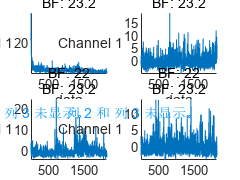

%查看数据
figure
tiledlayout(2,2)
for a = 1:4
    nexttile
    stackedplot(data{a,1}', DisplayLabels="Channel " + (1:numChannels))

    xlabel("data")
    title("BF: " + data{a,2})
end

划分数据集

[idxTrain,idxValidation] = trainingPartitions(numObservations, [0.7 0.3])

idxTrain =     51    39    10    11    38    57    23    42     9    21    37    45     4    34    52     8     6    55    41     7    40    30    50    19    48    26    46    27    22    29    33    12    53    20    31    18    32     5    25     2    59


idxValidation =     24    47    44    14     3    16    43    35     1    58    13    49    54    15    28    17    56    36



Train = data(idxTrain,:);
Validation = data(idxValidation,:);


排序

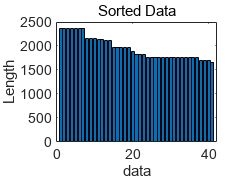

for h=1:numel(Train)/2
    sequence = Train{h,1};
    sequenceLengths(h) = size(sequence,2);
end

[sequenceLengths,idx] = sort(sequenceLengths,'descend');
figure
bar(sequenceLengths)
xlabel("data")
ylabel("Length")
title("Sorted Data")

**创建LSTM网络**

numHiddenUnits = 50;
numLayers = 3; % 增加的LSTM层数

layers = [sequenceInputLayer(numChannels)];

for layer = 1:numLayers
    layers = [layers
        lstmLayer(numHiddenUnits, 'OutputMode', 'last', 'Name', ['LSTMLayer' num2str(layer)])];
end

layers = [layers
    fullyConnectedLayer(2)
    regressionLayer];

超参数


XTrain=Train(idx,1);
YTrain=cell2mat(Train(idx,2));
XValidation=Validation(:,1);
YValidation=cell2mat(Validation(:,2));

%sgdm,adam，"best-validation-loss"
options = trainingOptions("sgdm", ...
    MaxEpochs=200, ...
    MiniBatchSize=12, ...
    ValidationData={XValidation YValidation}, ...
    OutputNetwork="last", ...
    InitialLearnRate=0.01, ...
    SequenceLength="shortest", ...
    Plots="training-progress", ...
    Verbose= false);




训练

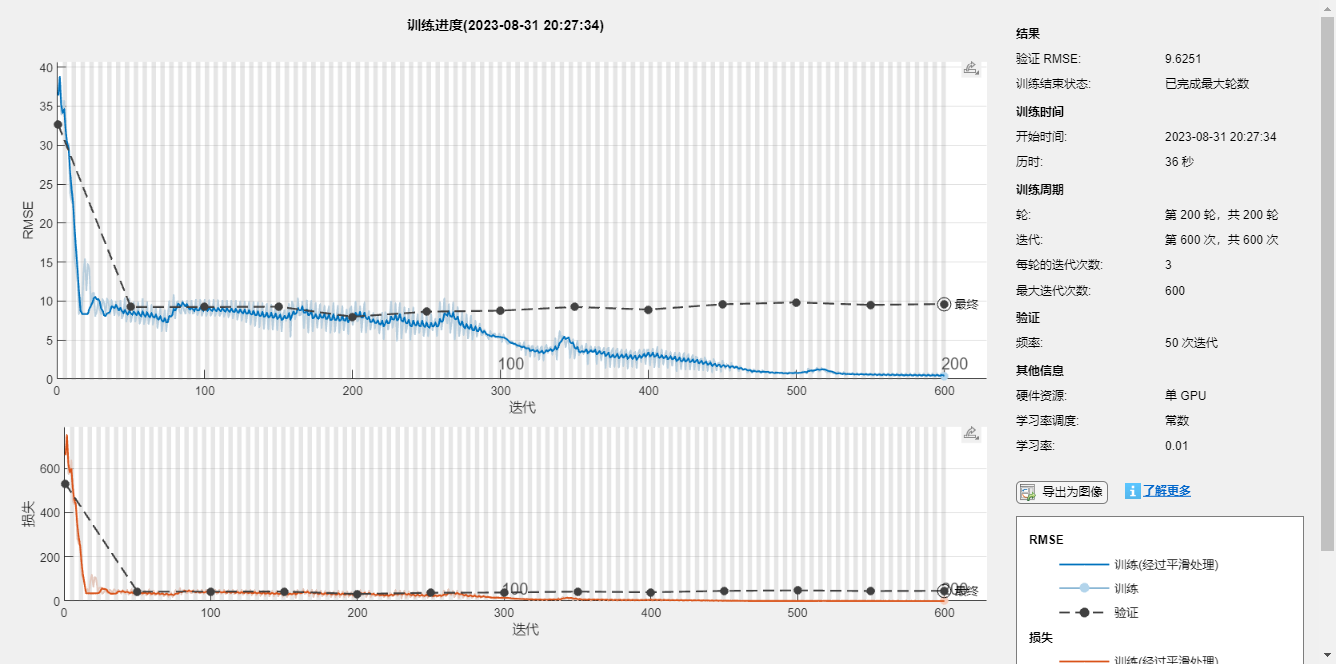


net = trainNetwork(XTrain,YTrain,layers,options);

## 预测与可视化

sigds = signalDatastore("F:\科研 sxh\MIE数据\深度学习\测试数据" , ...
    "IncludeSubfolders",false, ...
    "SignalVariableNames",["CH1", "BF","BMI"], ...
     "ReadOutputOrientation","row");

**读取测试集数据**

% 获取文件数目
numFiles = numel(sigds.Files);
% 初始化一个 cell 数组储存来文件长度
filelength = cell(numFiles, 1);

**提取特征**

ALLfeatures=[];%所有人的肌电特征
j=1;
while hasdata(sigds)
    features=[];%每个人的肌电特征        
    EMG = cell2mat(read(sigds)); %循环所有文件 
    num_samples = length(EMG);
    filelength{j} = EMG(1,2:end); %网络输出
    window_size= 50; % 窗口大小
    step_size = round(window_size * 0.5);% 重叠率0.5
    num_windows = floor((num_samples - window_size) / step_size) + 1;% 循环终点次数
    % 提取的特征feature_funcs = {@sd, @var, @max,@fzc, @emav, @tm,@iemg, @rms, @zc,@ssc}; 
    
    for i = 1:num_windows
        start_idx = (i - 1) * step_size + 1;
        end_idx = start_idx + window_size - 1;
        window_data = EMG(start_idx:end_idx,1);
        sd= jfemg('sd', window_data);
        var= jfemg('var', window_data);
       
        fzc= jfemg('fzc', window_data);
        emav= jfemg('emav', window_data);
        tm= jfemg('tm', window_data);
        iemg= jfemg('iemg', window_data);
        rms= jfemg('rms', window_data);
        zc= jfemg('zc', window_data);
        ssc= jfemg('ssc', window_data);
        % 在这里添加你对窗口数据的特征提取操作
        % 对特征函数应用 transform 函数
       
        feature = [sd,var,fzc, emav, tm,iemg, rms, zc,ssc];
        features=[features;feature];
    end


主成分分析

    % 特征归一化（标准化）
    normalized_features = zscore(features);
    % r=corrcoef(normalized_features); 获取相关系数矩阵
    coeff = pca(normalized_features);
    disp('主成分分析的主成分系数：');
    disp(coeff);
    
    % 将数据投影到前两个主成分上
    num_components = 3;
    PCAfeature = normalized_features * coeff(:, 1:num_components);

%     PCAfeatures=[PCAfeature';EMG(1:length(normalized_features),2)';EMG(1:length(normalized_features),3)',;EMG(1:length(normalized_features),5)'];
%     features=mat2cell(PCAfeatures,1);
    ALLfeatures{j}=PCAfeature';
    j=j+1
end

主成分分析的主成分系数：


    0.4366    0.0181    0.1437    0.0589    0.1215   -0.4754   -0.2499    0.6198    0.3124
    0.3778    0.2957   -0.3661   -0.0888   -0.0788   -0.0371    0.6186    0.2621   -0.4110
   -0.0774    0.4126    0.0963    0.8631   -0.2629    0.0195   -0.0070    0.0046   -0.0055
    0.4032   -0.1569    0.3443    0.0834    0.1023    0.6737   -0.2279    0.2155   -0.3529
    0.2894    0.3813   -0.5622   -0.1562   -0.1807    0.2702   -0.4843   -0.1527    0.2586
    0.4324   -0.0439    0.2068    0.0718    0.0979    0.1925    0.4685   -0.3494    0.6123
    0.4373    0.0236    0.1355    0.0578    0.1184   -0.4487   -0.2208   -0.5961   -0.4088
   -0.1855    0.5707    0.0986   -0.0625    0.7873    0.0795   -0.0055    0.0014    0.0001
   -0.0409    0.4937    0.5750   -0.4472   -0.4726   -0.0245    0.0048   -0.0012    0.0014



j = 2

主成分分析的主成分系数：


    0.4190    0.0652    0.0173    0.0085   -0.1538   -0.0070    0.5519   -0.3356   -0.6155
    0.4093    0.1180    0.0338    0.0714   -0.0343    0.8186   -0.3376   -0.1485    0.0706
   -0.0348    0.6452   -0.5449   -0.5265    0.0914   -0.0009    0.0034    0.0056   -0.0008
    0.4113   -0.0203   -0.0025   -0.1009   -0.2521   -0.5031   -0.4630   -0.4985    0.2018
    0.3098    0.1952    0.1212    0.2439    0.8678   -0.1917   -0.0415   -0.0120   -0.0070
    0.4193    0.0224    0.0116   -0.0382   -0.1892   -0.1708   -0.2858    0.7528   -0.3298
    0.4194    0.0659    0.0196    0.0127   -0.1428   -0.0267    0.5306    0.2236    0.6831
   -0.1608    0.5962   -0.0284    0.7185   -0.2991   -0.1000   -0.0466   -0.0066    0.0005
   -0.1138    0.4084    0.8280   -0.3607   -0.0673   -0.0077   -0.0010    0.0009   -0.0004



j = 3

主成分分析的主成分系数：


    0.4219    0.0742    0.0099   -0.0616    0.1196   -0.0233    0.5636    0.5475    0.4246
    0.4129    0.1120   -0.0063    0.0519    0.0701    0.8245   -0.3049    0.1211   -0.1479
   -0.0601    0.5090    0.7911   -0.2169   -0.2538   -0.0005   -0.0058    0.0014   -0.0019
    0.4139   -0.0059    0.0145   -0.2236    0.1430   -0.5004   -0.4608    0.3797   -0.3887
    0.2917    0.1974   -0.0981    0.7015   -0.5766   -0.1913   -0.0688    0.0030    0.0191
    0.4211    0.0296    0.0164   -0.1504    0.1392   -0.1428   -0.3095   -0.5379    0.6116
    0.4224    0.0739    0.0102   -0.0499    0.1121   -0.0543    0.5232   -0.5020   -0.5218
   -0.1737    0.5923   -0.0711    0.4075    0.6604   -0.0953   -0.0505    0.0050   -0.0008
   -0.0751    0.5716   -0.5990   -0.4617   -0.3087    0.0160    0.0115   -0.0055    0.0015



j = 4

主成分分析的主成分系数：


    0.4114    0.0942    0.0392   -0.0020   -0.1490    0.1021    0.5481   -0.3889   -0.5797
    0.4043    0.1369    0.0649    0.0469   -0.0759    0.7305   -0.4892   -0.1505    0.1000
   -0.0829    0.7619   -0.4173   -0.4738    0.1171   -0.0177   -0.0016    0.0035    0.0013
    0.4048   -0.0074    0.0097   -0.1297   -0.2379   -0.5917   -0.3205   -0.4876    0.2683
    0.2910    0.2383    0.1793    0.3800    0.8037   -0.1862   -0.0348   -0.0086   -0.0105
    0.4114    0.0368    0.0268   -0.0713   -0.1967   -0.2361   -0.2735    0.6942   -0.4152
    0.4119    0.0930    0.0424    0.0058   -0.1379    0.0702    0.5294    0.3260    0.6399
   -0.2216    0.5246    0.1171    0.6730   -0.4446   -0.1007   -0.0358   -0.0060    0.0004
   -0.1544    0.2235    0.8784   -0.3925   -0.0216   -0.0052    0.0091    0.0011   -0.0000



j = 5

主成分分析的主成分系数：


    0.4133    0.0848    0.0420    0.0270   -0.1435    0.0404    0.5586   -0.4745   -0.5101
    0.4056    0.1132    0.0707    0.0605   -0.0749    0.7863   -0.3991   -0.1274    0.1213
   -0.0680    0.7873   -0.3860   -0.4735    0.0482   -0.0044   -0.0050    0.0019   -0.0022
    0.4069    0.0005    0.0034   -0.0795   -0.2466   -0.5527   -0.4004   -0.4427    0.3247
    0.2920    0.2063    0.2211    0.2113    0.8655   -0.1619   -0.0568   -0.0057   -0.0130
    0.4130    0.0351    0.0256   -0.0329   -0.2060   -0.2004   -0.2848    0.6303   -0.5153
    0.4137    0.0863    0.0450    0.0272   -0.1320   -0.0010    0.5310    0.4066    0.5950
   -0.2085    0.5237    0.1498    0.7497   -0.2958   -0.0910   -0.0451   -0.0047    0.0011
   -0.1552    0.1863    0.8776   -0.3957   -0.1196   -0.0029    0.0079   -0.0015    0.0000



j = 6

ALLfeatures=ALLfeatures';
data=[ALLfeatures,filelength];

XTest=ALLfeatures;
YTest = cell2mat(filelength);
pTest = predict(net,XTest, SequenceLength="shortest");

**可视化**

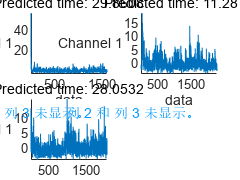

figure
tiledlayout(2,2)
for i = 1:3
    nexttile
    stackedplot(XTest{i}',DisplayLabels="Channel " + (1:numChannels))

    xlabel("data")
    title("Predicted time: " + string(pTest(i)))
end

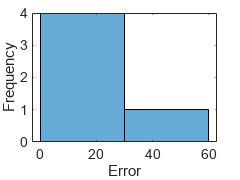

%在直方图中可视化均方误差。

figure
histogram(mean((pTest - YTest).^2,2))
xlabel("Error")
ylabel("Frequency")


%计算总体均方根误差。
rmse = sqrt(mean((YTest-pTest).^2))

rmse = 1×2 single 行向量
    4.2556    3.7798


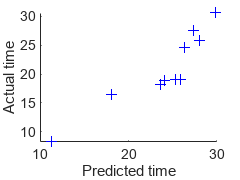

%将预测频率与实际频率绘制。

figure
scatter(pTest,YTest, "b+");
xlabel("Predicted time")
ylabel("Actual time")
hold on


% m = 200;
% M=250;
% xlim([m M])
% ylim([100 M])
% plot([m M], [m M], "r--")








function varargout = trainingPartitions(numObservations,splits)
%TRAININGPARTITONS Random indices for splitting training data
%   [idx1,...,idxN] = trainingPartitions(numObservations,splits) returns
%   random vectors of indices to help split a data set with the specified
%   number of observations, where SPLITS is a vector of length N of
%   partition sizes that sum to one.
%
%   Example: Get indices for 50%-50% training-test split of 500
%   observations.
%   [idxTrain,idxTest] = trainingPartitions(500,[0.5 0.5])
%
%   Example: Get indices for 80%-10%-10% training, validation, test split
%   of 500 observations. 
%   [idxTrain,idxValidation,idxTest] = trainingPartitions(500,[0.8 0.1 0.1])

arguments
    numObservations (1,1) {mustBePositive}
    splits {mustBeVector,mustBeInRange(splits,0,1,"exclusive"),mustSumToOne}
end

numPartitions = numel(splits);
varargout = cell(1,numPartitions);

idx = randperm(numObservations);

idxEnd = 0;

for i = 1:numPartitions-1
    idxStart = idxEnd + 1;
    idxEnd = idxStart + floor(splits(i)*numObservations) - 1;

    varargout{i} = idx(idxStart:idxEnd);
end

% Last partition.
varargout{end} = idx(idxEnd+1:end);

end

function mustSumToOne(v)
% Validate that value sums to one.

if sum(v,"all") ~= 1
    error("Value must sum to one.")
end

end
